rng(14);
n=500;
% rand1 = exprnd(.16,[1,floor(n/3)]);
% rand1 = rand1(rand1<=0.6);
% rand1 = rand1(rand1>0);
% rand3 = exprnd(0.12,[1,floor(n/3)])+0.5;
% rand3 = rand3(rand3<=1);
% rand3 = rand3(rand3>0.5);
lower = 0;
peak = 0.2;
upper = 1;
pd = makedist('Triangular','A',lower,'B',peak,'C',upper);
y = random(pd,1,n);

% y = ([rand1])

% y = y(y<=1);
sum(y<0)

ans = 0

sum(y>1)

ans = 0



% d = 11;
knots = [-0.0250:0.1:1.075];
orig_knots = knots;
knots(end-1) = 1;
knots(2) = 0;
constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','none','TolFun', 1e-10);

flag=11;
solve_this = @(a) (constraintFunc(a));
% initial = [-2.5, log(0.25), log(0.6),log(1.4), log(2.2), log(1.5),...
%     log(2.4), log(2.1), log(1.1), ...
%     log(1.15),log(1.2),log(0.7), log(0.75), log(0.8),...
%     log(0.4),log(0.5), log(0.6), log(0.5), log(0.4), log(0.3), ...
%     -2.5];
initial = [-2.5, log(1.6),log(2.3), log(2.4),...
    log(1.6), log(0.7), log(0.6), log(0.5), log(0.2), -2.5];
initial_guess = fsolve(solve_this, initial, options)

initial_guess =    -2.4988    0.4773    0.8432    0.8860    0.4773   -0.3529   -0.5080   -0.6910   -1.6083   -2.4997




syms func2(x)
chosen_theta = initial_guess

chosen_theta =    -2.4988    0.4773    0.8432    0.8860    0.4773   -0.3529   -0.5080   -0.6910   -1.6083   -2.4997


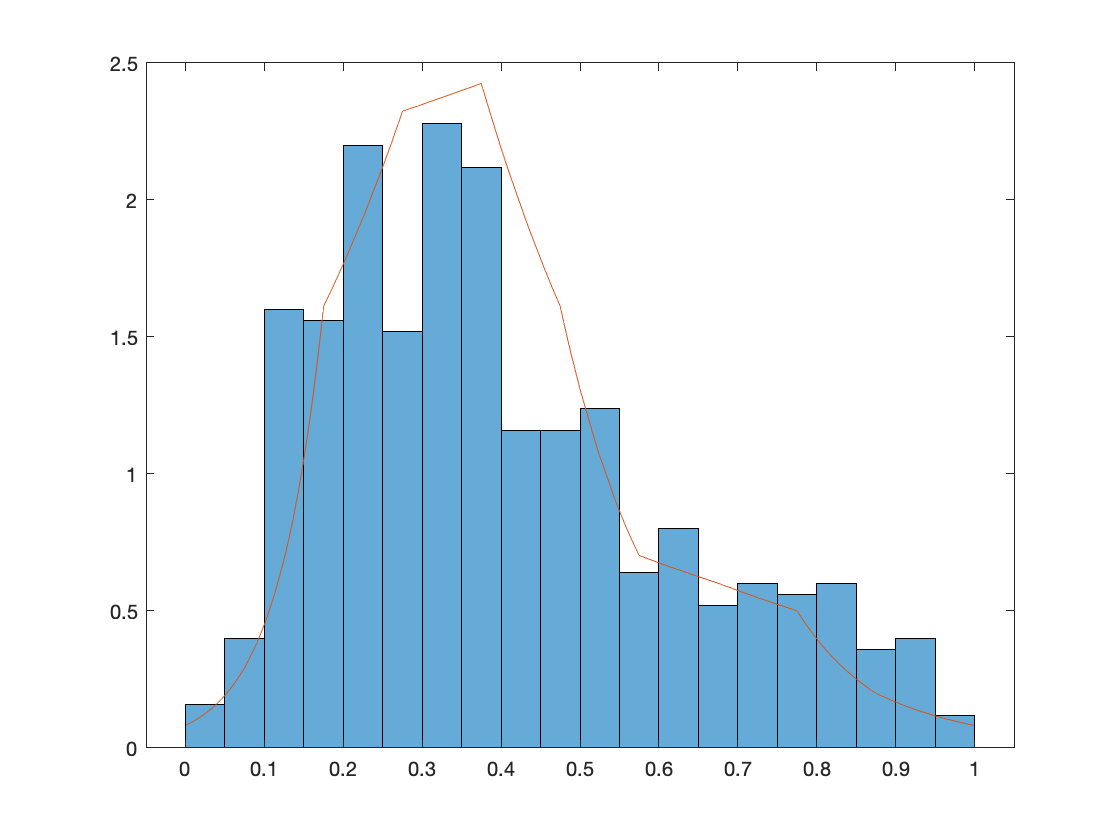

func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))),... 
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))) );
histogram(y, 'Normalization','pdf','BinWidth',0.05)
hold on
fplot(func2, [0,1])
hold off

% saveas(gcf,'InitialHist.png')


num_iters = 15000;
burn_in = 1;
proposal_scale = 1e-2

proposal_scale = 0.0100


% 
ll_function = @(x) ll_density(x, knots, y);
constraintFunc = @(x) logspline_constraint(knots, x);
dConstraintFunc = @(x) dlogspline_constraint(knots, x);
[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess', ll_function, ...
    constraintFunc, dConstraintFunc);

The current MH ratio is: -4.242561e+00
The current MH ratio is: 1.181439e+00


mean(accepts)
sum(accepts)
save("MH_logsplineDraws_lessknots_longrun.mat",'samples');

% plot(accepts)

% I will need to get a point estimator at some point, but for now let's
% just choose a theta and see if I can plot it.
samples = matfile("MH_logsplineDraws_lessknots_longrun.mat");
samples = samples.samples;
burn_in = 5000;
samples = samples(:,burn_in:end)
mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i)./(var(samples')'), 2);
end
[~,min_index] = min(mag_mean_diff);
save("mag_mean_diff.mat",'mag_mean_diff');

% fplot(y, [0,1])
[~,num_samples] = size(samples);

% knots = orig_knots;
% knots(end-1) = 1;
% knots(2) = 0;

mean_value = mean(samples')';
mean_diff = samples - mean_value;
[~,num_cols] = size(mean_diff);
mag_mean_diff = zeros(1,num_cols);
for i=1:num_cols
    mag_mean_diff(i) = norm(mean_diff(:,i), 2);
end
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
% my_plot = fplot(func1, [0,1]);
% set(my_plot, 'LineWidth',2);
% my_plot
[~,num_of_samples] = size(samples)
% num_of_knots = length(knots) - 2;
% x_values = unique(sort([(1:20)/20, knots(2:(end-1))]));
d = length(knots);
x_values = knots(2:(d-1));
% logspline_values = zeros(num_of_samples, length(x_values));

for i = 1:num_of_samples
    fprintf(1,'\b\b\b\b\b\b%6.0i',i);
    chosen_theta = samples(:,i);
%     func2(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
%         (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
%         (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
%         (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
%         (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
%         (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
%         (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
%         (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
%         (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))));
    for j=1:(length(knots)-2)
        logspline_values(i,j) = exp(logspline_density(knots(j+1),knots,chosen_theta));
%         logspline_values(i,j) = double(func2(x_values(j)));
    end
end
save("logspline_values.mat",'logspline_values');
% logspline_values = matfile("logspline_values.mat");
% logspline_values = logspline_values.logspline_values;

upper95s = zeros(1,length(x_values));
lower5s = zeros(1,length(x_values));
for i=1:(length(x_values))
    upper95s(i) = quantile(logspline_values(:,i),0.95);
    lower5s(i) = quantile(logspline_values(:,i),0.05);
end

histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'w')
hold on
plot1 = plot(x_values, upper95s,'LineWidth',2, 'LineStyle', "--", "Color", 'r');
% plot1 = fplot(func1,'LineWidth',2, 'LineStyle', "--", "Color", 'r');
% set(my_plot);
plot1
hold off


hold on
plot2 = plot(x_values, lower5s,'LineWidth',2, 'LineStyle', "--", "Color", 'b');
% plot1 = fplot(func1,'LineWidth',2, 'LineStyle', "--", "Color", 'r');
% set(my_plot);
plot2
hold off
saveas(gcf,'UppersLowersNoHist.png')

saveas(gcf,'UppersLowers.png')


hold on
[~,min_index] = min(mag_mean_diff);
chosen_theta = samples(:,min_index);
syms func3(x)
func3(x) = piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))), ...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))) );
plot3 = fplot(func3, [0,1], 'LineWidth', 2, 'Color', 'g');
plot3
syms tri(x)
tri(x) = piecewise( (lower <= x)&(x < peak),2*(x-lower)/((upper - lower)*(peak-lower)), ...
    (x == peak), 2/(upper-lower),...
    (peak < x)&(x <= upper),2*(upper-x)/((upper-lower)*(upper-peak)) );
plot4 = fplot(tri, [0,1], 'LineWidth', 2, "LineStyle", ":", 'Color', 'm');
plot4

constraintFunc = @(x) logspline_constraint(knots, x);
options = optimoptions('fsolve','Display','iter-detailed','TolFun', 1e-3, 'MaxFunctionEvaluations', 1e3, 'MaxIterations', 1e3);
minimize_this = @(a) KL_divergence(a);

initial = [-1.3,log(double(tri(knots(3)))),log(double(tri(knots(4)))),log(double(tri(knots(5)))),...
    log(double(tri(knots(6)))), ...
    log(double(tri(knots(7)))),log(double(tri(knots(8)))), ...
    log(double(tri(knots(9)))), log(double(tri(knots(10)))),-1.3];

A = [];
b = [];
Aeq = [];
beq = [];
lb = [];
ub = [];
% The following lines solve for the "best logspline curve." Since this
% should be the same regardless of the data, I precalculated it.
% nonlcon = @(a)optim_constraint(knots,a);
% closest_logspline_to_truth = fmincon(minimize_this,initial,A,b,Aeq,beq,lb,ub,nonlcon)
closest_logspline_to_truth = [-1.3076,0.6549,0.6232,0.4469,0.2493,0.0266,-0.2374,-0.5887,-1.1669,-1.3142];

% initial_guess = x;
syms func2(x)
chosen_theta = closest_logspline_to_truth;
% chosen_theta = x;

func2(x) =  piecewise((knots(2) < x)&(x <= knots(3)),exp(chosen_theta(2)*(x-knots(2))/(knots(3)-knots(2)) + chosen_theta(1)*(knots(3)-x)/(knots(3)-knots(2))), ...
    (knots(3) < x)&(x <= knots(4)),exp(chosen_theta(3)*(x-knots(3))/(knots(4)-knots(3)) + chosen_theta(2)*(knots(4)-x)/(knots(4)-knots(3))), ...
    (knots(4) < x)&(x <= knots(5)),exp(chosen_theta(4)*(x-knots(4))/(knots(5)-knots(4)) + chosen_theta(3)*(knots(5)-x)/(knots(5)-knots(4))), ...
    (knots(5) < x)&(x <= knots(6)),exp(chosen_theta(5)*(x-knots(5))/(knots(6)-knots(5)) + chosen_theta(4)*(knots(6)-x)/(knots(6)-knots(5))), ...
    (knots(6) < x)&(x <= knots(7)),exp(chosen_theta(6)*(x-knots(6))/(knots(7)-knots(6)) + chosen_theta(5)*(knots(7)-x)/(knots(7)-knots(6))), ...
    (knots(7) < x)&(x <= knots(8)),exp(chosen_theta(7)*(x-knots(7))/(knots(8)-knots(7)) + chosen_theta(6)*(knots(8)-x)/(knots(8)-knots(7))), ...
    (knots(8) < x)&(x <= knots(9)),exp(chosen_theta(8)*(x-knots(8))/(knots(9)-knots(8)) + chosen_theta(7)*(knots(9)-x)/(knots(9)-knots(8))), ...
    (knots(9) < x)&(x <= knots(10)),exp(chosen_theta(9)*(x-knots(9))/(knots(10)-knots(9)) + chosen_theta(8)*(knots(10)-x)/(knots(10)-knots(9))),...
    (knots(10) < x)&(x <= knots(11)),exp(chosen_theta(10)*(x-knots(10))/(knots(11)-knots(10)) + chosen_theta(9)*(knots(11)-x)/(knots(11)-knots(10))) );
plot5 = fplot(func2, [0,1], 'LineWidth', 2, "LineStyle", "-.", 'Color', 'k');

legend([plot1, plot3,plot5,plot4 plot2],'Upper 95% of Parameters','Estimated Logspline',...
    'Closest Logspline to the Truth','True PDF', 'Lower 5% of Parameters')
% legend(["this", "that", "these"])
hold off

saveas(gcf,'UppersLowersMiddle_lessknots.png')
% hold on
% histogram(y, 'Normalization','pdf','BinWidth',0.01, 'FaceColor', 'c')
% legend(character_array)
% hold off